Import raw data

addpath('path_to_PBLR')
addpath(genpath('./'))
addpath PROPACK;
addpath Rank
addpath example_data
iniData = readtable('raw.txt','Delimiter','\t','ReadRowNames',true,...
    'ReadVariableNames',true);

Preprocessing data

tic;
minGenes = 0; minCells = 0; libararyflag = 0; logNormalize = 1;  
proData = preprocessing(iniData, minCells, minGenes, libararyflag,logNormalize);
M = proData.data;

Select informative genes used for clustering

id = gene_selection(M);

Clustering

M0 = M(id,:);
K = []; % the cluster numbers can be given by user.
numCores = 1; % defined by user
system_used = 'Mac';
accelerate = 1;
label = [];
[group,coph] = clusteing(iniData,M0,K,numCores,system_used,accelerate,label);

Loading required package: ggplot2
Loading required package: cowplot

Attaching package: ‘cowplot’

The following object is masked from ‘package:ggplot2’:

    ggsave

Loading required package: Matrix

Attaching package: ‘dplyr’

The following objects are masked from ‘package:stats’:

    filter, lag

The following objects are masked from ‘package:base’:

    intersect, setdiff, setequal, union

------------------------------------------------------------------------------
You have loaded plyr after dplyr - this is likely to cause problems.
If you need functions from both plyr and dplyr, please load plyr first, then dplyr:
library(plyr); library(dplyr)
------------------------------------------------------------------------------

Attaching package: ‘plyr’

The following objects are masked from ‘package:dplyr’:

    arrange, count, desc, failwith, id, mutate, rename, summarise,
    summarize


Attaching package: ‘data.table’

The following objects are masked from ‘package:dplyr’:

    b

Select boundary function through visualizing. 

The boundary functions are divided into three categories:

1: exponetial function; 

2: simple piecewise function;

3: sophisticated piecewise function.

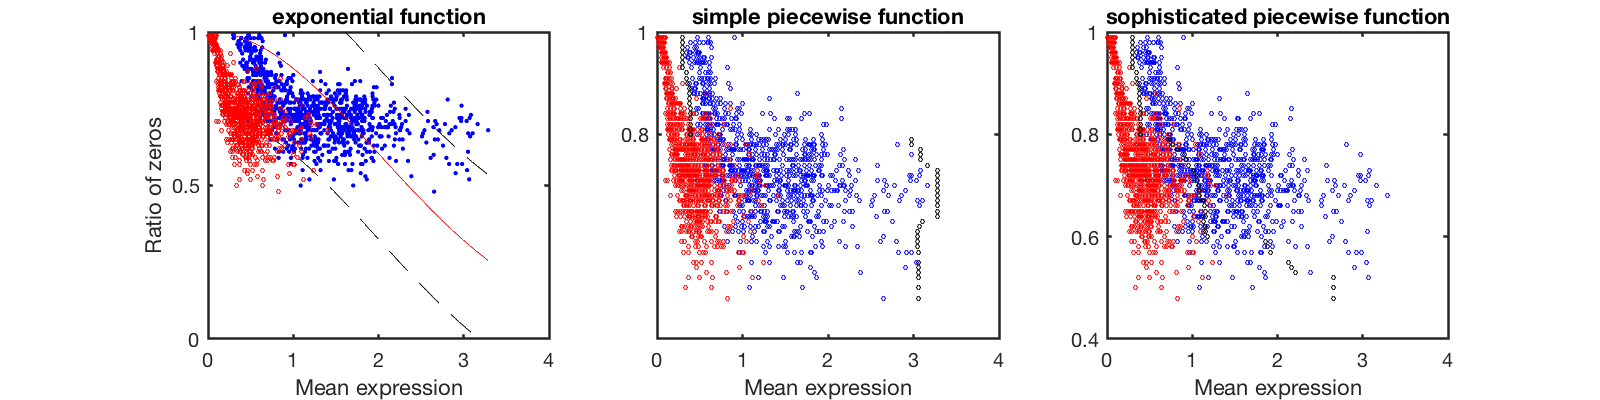

boundary_selection(M);

Run PBLR with selected boundary function

boundary_function = 3;
imputation_all = 1;
accelate = true;
X = PBLR_main(M,id,group,boundary_function,imputation_all,numCores,accelate);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 1).
Imputing the submatrix of selected genes across cells of each cluster: 
Imputing the remaining submatrix: 


toc;

Elapsed time is 47.105672 seconds.


Export the imputed matrix

if isequal(imputation_all,true)
    id = 1:size(M,1);
end
T = array2table(X,'VariableNames',proData.cells,'RowNames',proData.genes(id));
writetable(T,'PBLR_impute.txt','Delimiter','\t','WriteRowNames',1);